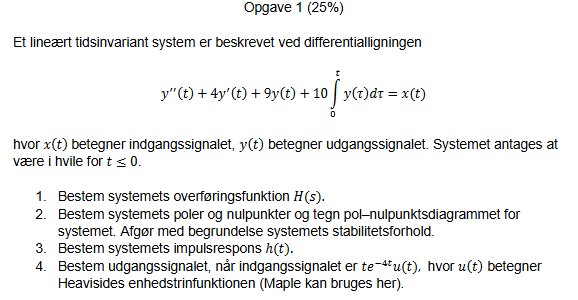

clear all; clc;

### 1. Bestem systemets overføringsfunktion 𝐻(𝑠).

disp('================================================================');
disp('DELOPGAVE 1: BESTEM SYSTEMETS OVERFØRINGSFUNKTION H(s)');
disp('================================================================');
disp(' ');

a = [1, 4, 9, 10];    % Nævner koefficienter: s³ + 4s² + 9s + 10
b = [1, 0];           % Tæller koefficienter: s

[num_tf, den_tf, tf_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

% Vis overføringsfunktionen symbolsk
syms s;
H_s = poly2sym(num_tf, s) / poly2sym(den_tf, s);

disp(' ');
disp('SVAR PÅ DELOPGAVE 1:');
disp('====================');
disp(['H(s) = ' char(H_s)]);
disp(' ');

### 2. Bestem systemets poler og nulpunkter og tegn pol–nulpunktsdiagrammet for systemet. Afgør med begrundelse systemets stabilitetsforhold.

disp('================================================================');
disp('DELOPGAVE 2: POLER, NULPUNKTER OG STABILITET');
disp('================================================================');
disp(' ');

disp('Udfører pol-nulpunktsanalyse med ElektroMatBibTrinvis...');
disp(' ');

[poler, nulpunkter, stabilitet, forklaringsOutput] = ...
    ElektroMatBibTrinvis.polNulpunktsDiagramMedForklaring(b, a, 'Opgave 1: Integro-Differentialsystem');

### 3. Bestem systemets impulsrespons ℎ(𝑡).

disp('================================================================');
disp('           DELOPGAVE 3 - SYSTEMETS IMPULSRESPONS');
disp('================================================================');
disp(' ');

syms t;

[h_t, impuls_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

### 4. Bestem udgangssignalet, når indgangssignalet er 𝑡𝑒ି ସ௧ 𝑢(𝑡), hvor 𝑢(𝑡) betegner Heavisides enhedstrinfunktionen (Maple kan bruges her)

disp('================================================================');
disp(' DELOPGAVE 4 - BEREGN UDGANGSSIGNAL y(t)');
disp('================================================================');
disp(' ');

syms s t;

% Definer indgangssignalet som givet i opgaven
x_t = t * exp(-4*t);  % te^(-4t)u(t) - u(t) er implicit

% Lad biblioteket beregne Laplace-transformationen automatisk
[X_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(x_t, t, s);

% Nu beregn udgangssignalet
[y_t, udgang_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);

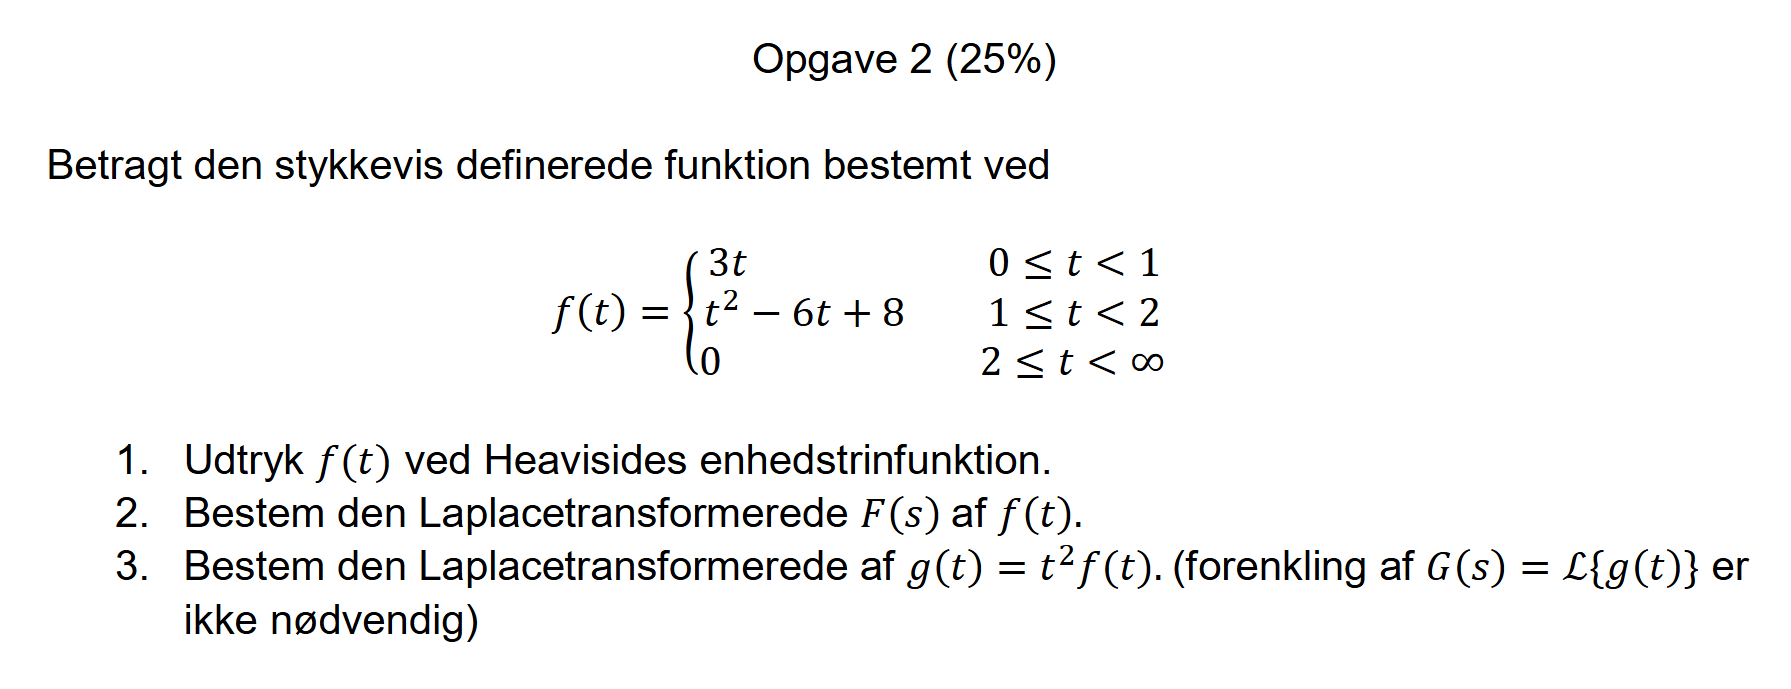

clear all; clc;

### 1. Udtryk 𝑓(𝑡) ved Heavisides enhedstrinfunktion

disp('================================================================');
disp('DELOPGAVE 1: Udtryk 𝑓(𝑡) ved Heavisides enhedstrinfunktion');
disp('================================================================');
disp(' ');

syms t;
func_liste = {3*t, t^2 - 6*t + 8, 0};
graenser = [0, 1, 2, inf];
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring(func_liste, graenser, t);

disp(' ');
disp('SVAR PÅ DELOPGAVE 1:');
disp('====================');
disp(['f(t) = ' char(f_t)]);
disp(' ');

### 2. Bestem den Laplacetransformerede 𝐹(𝑠) af 𝑓(𝑡).

disp('================================================================');
disp('DELOPGAVE 2: Bestem den Laplacetransformerede 𝐹(𝑠) af 𝑓(𝑡)');
disp('================================================================');
disp(' ');

syms s;
[F_s, forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);

disp(['F(s) = ' char(F_s)]);

### 3. Bestem den Laplacetransformerede af 𝑔(𝑡) = 𝑡ଶ𝑓(𝑡). (forenkling af 𝐺(𝑠) = ℒ{𝑔(𝑡)} er ikke nødvendig)

disp('================================================================');
disp('DELOPGAVE 3: Bestem den Laplacetransformerede af 𝑔(𝑡) = 𝑡ଶ𝑓(𝑡). (forenkling af 𝐺(𝑠) = ℒ{𝑔(𝑡)} er ikke nødvendig)');
disp('================================================================');
disp(' ');

[G_s, forklaring3] = ElektroMatBibTrinvis.diffLaplaceMedForklaring(F_s, s, 2);

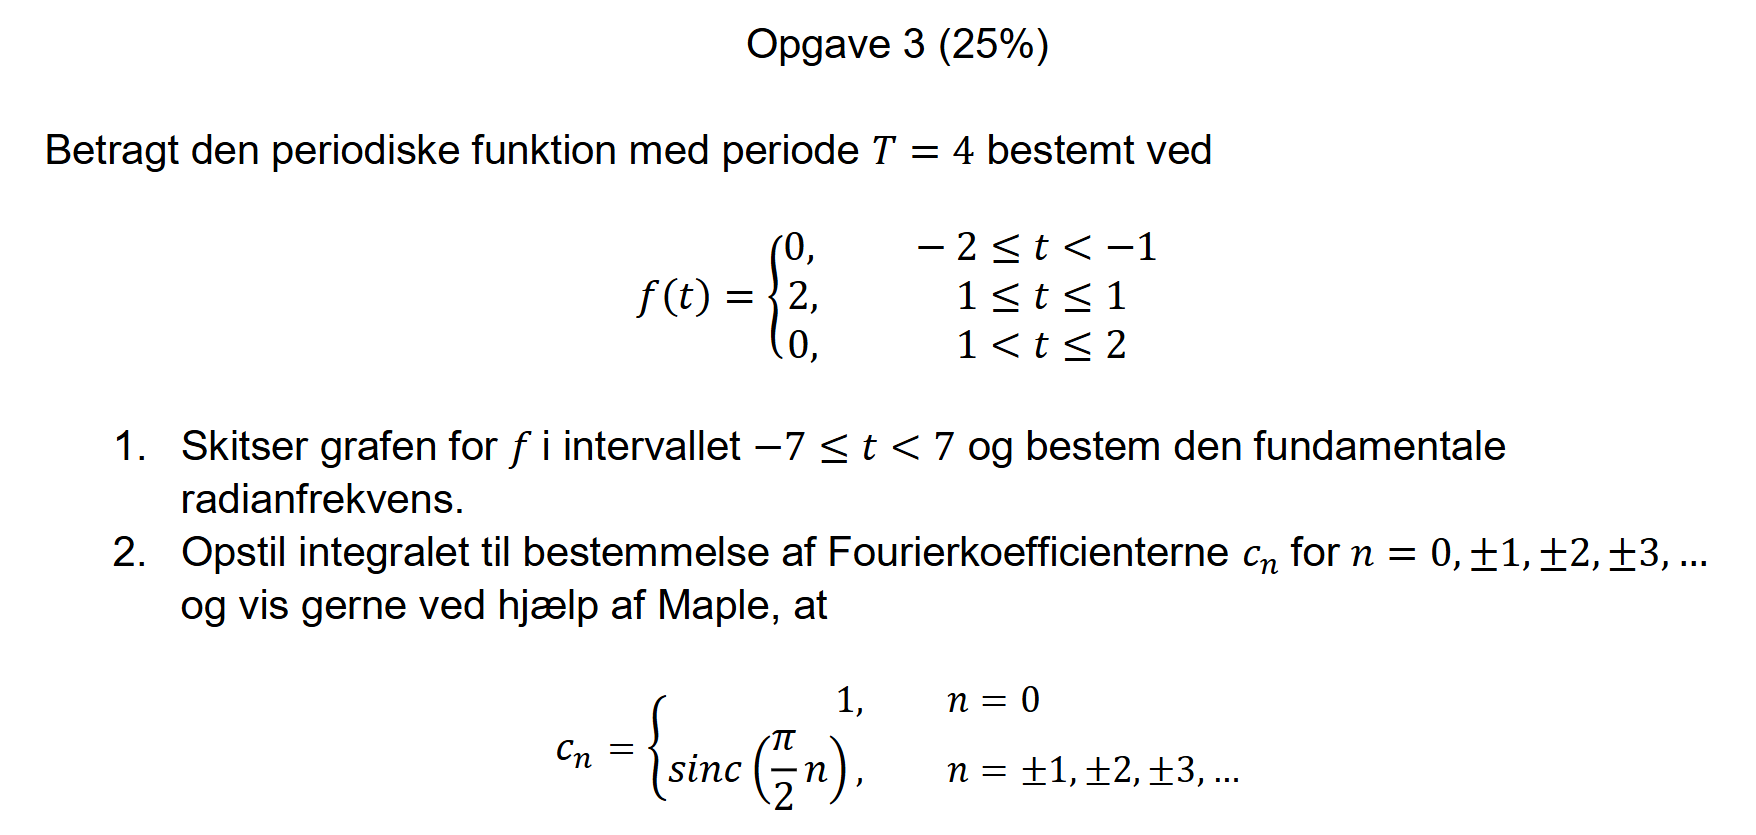

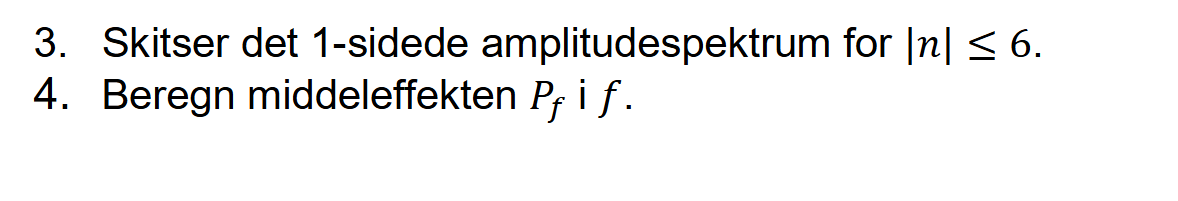

clear all; clc;

### 1. Skitser grafen for 𝑓 i intervallet −7 ≤ 𝑡 < 7 og bestem den fundamentale radianfrekvens.

### 2. Opstil integralet til bestemmelse af Fourierkoefficienterne 𝑐௡ for 𝑛 = 0, ±1, ±2, ±3, … og vis gerne ved hjælp af Maple, a

### 3. Skitser det 1-sidede amplitudespektrum for |𝑛| ≤ 6.

### 4. Beregn middeleffekten 𝑃௙ i 𝑓.